% parameter 
R = 1000;               % 탑재체부터 지표까지의 거리 [m]
c = 3*10^8;             % 광속 [m]
dx = 10;                % input data의 거리단위 [m]
x = 0 : dx : 300;       % 총 지표의 input data [m]
length_x = length(x);   % input data의 벡터길이

fc = 12;                                % 운용주파수 [GHz]
lambda = c/(fc*10^9)                    % 파장 [m]

lambda = 0.0250

L = 1.5;                                % 안테나 길이 [m], 방위(azimuth)에 영향
W = 1.5;                                % 안테나 폭 [m], 고도(elevation)에 영향
theta_az = 0.886*(lambda/L)*10^2;       % 안테나 빔 폭(azimuth) [ °]
theta_el = 0.886*(lambda/W)*10^2;       % 안테나 빔 폭(elevation) [ °]

dt = 0.01;
t = 0 : dt : 10;                % [ns]
chirp_gain = 1;
chirp_fo = 1;
chirp_delta_tau = 0;
chirp_mu = 1;

noiseSD = 8;
%--------------------------------------------------------------------------------------------

ground = [0 0 0 0 1 1 2 2 2 2 4 4 4 4 1 1 1 1 -2 -2 -3 -3 -3 -3 -1 -1 -1 0 0 1 1];

% 거리측정 
new_ground = R + ground;                    % [m]
time = (2*new_ground/c)*10^9;               % [ns]
time_with_noise = time + noiseSD*randn(1,length_x);
R_with_noise = (time_with_noise*c/2)*10^-9;
ground_with_noise = R_with_noise - R;
final_ground = (ground_with_noise);    % 최종 ground input data

% 지표면에 비치는 빔의 길이
length_az = R/cos(deg2rad(theta_az));
length_el = R/cos(deg2rad(theta_el));
BeamWidth_xlength = 2*length_az*sin(deg2rad(theta_az))  % x축[m]

BeamWidth_xlength = 51.5568

BeamWidth_ylength = 2*length_el*sin(deg2rad(theta_el))  % y축[m]

BeamWidth_ylength = 51.5568


% 최종 빔 폭 (정수로 나타냄)
beamwidth = round(BeamWidth_xlength)        % [m]        

beamwidth = 52

beamwidth_dx = round(BeamWidth_xlength/dx)  % ground data를 몇개씩 분석할 지 정함!

beamwidth_dx = 5


%---------------------------------------------------------------------------------------------
% 빔 폭에 걸쳐진 input data를 호출하여 거리에 따른 시간 분석.
% 50m 빔폭

first_input = ground(1:beamwidth_dx+1)     % 행렬 호출!

first_input =      0     0     0     0     1     1


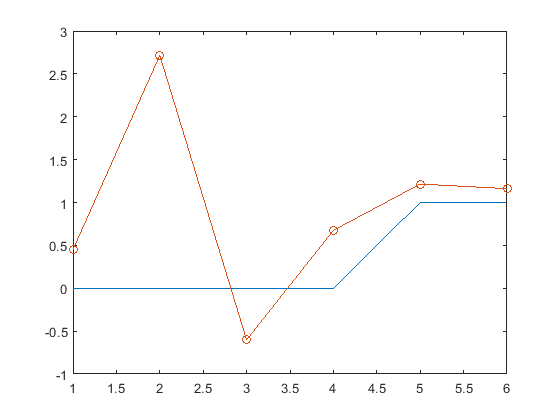

plot(first_input);
hold on;
first_input_with_noise = ground_with_noise(1:beamwidth_dx+1);
plot(first_input_with_noise,'Marker','o');
hold off;

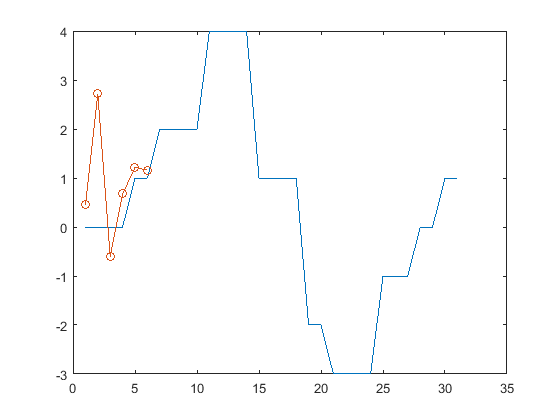


plot(ground);
hold on;
plot(first_input_with_noise,'Marker','o');  % 그래프의 '점'이 의미하는 것은 빔 폭에 따른 높이 데이터를 의미
hold off;                                   % 50m의 빔폭을 가지고 있을 때, 총 6개의 높이 데이터가 들어옴

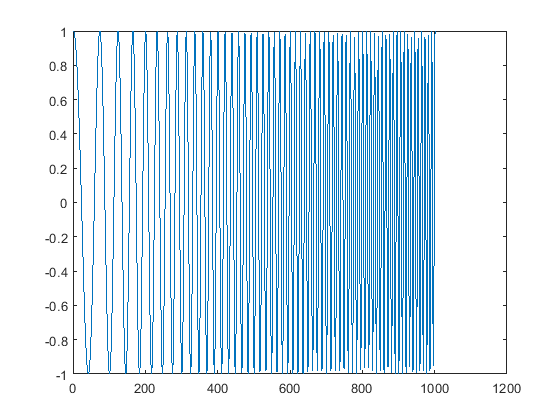


xt = chirp_gain.*cos(2*pi.*(chirp_fo*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
plot(xt);


% signal이 지표에 부딪쳐 다시 되들어오는 시간과, signal들의 시간차이
t1 = 2*R/c                  

t1 = 6.6667e-06

arived_t1 = t1*10^6             % [us] 처음 되돌아오는 시간.

arived_t1 = 6.6667

t2 = 2*(R+1)/c

t2 = 6.6733e-06

diff_t = abs(t1-t2)*10^9        % [ns] 높이 차이로 인한 signal들의 시간차

diff_t = 6.6667

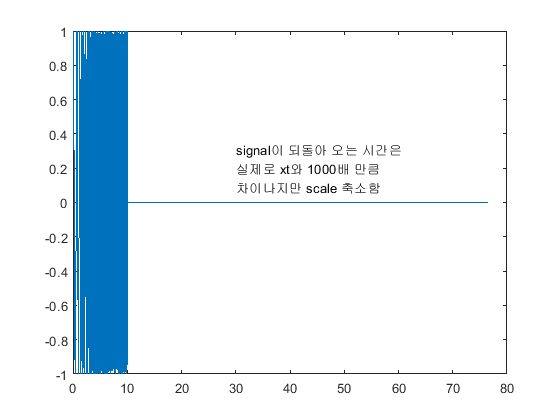


st = [xt, zeros(1,round(arived_t1*10^3))];
plot((0:length(st)-1)*dt,st);   % 실제 zeros의 길이는 xt에비해 1000배 차이나지만 눈에 보이기 위해 scale 줄임
text(30,0.2,{'signal이 되돌아 오는 시간은','실제로 xt와 1000배 만큼', '차이나지만 scale 축소함'});

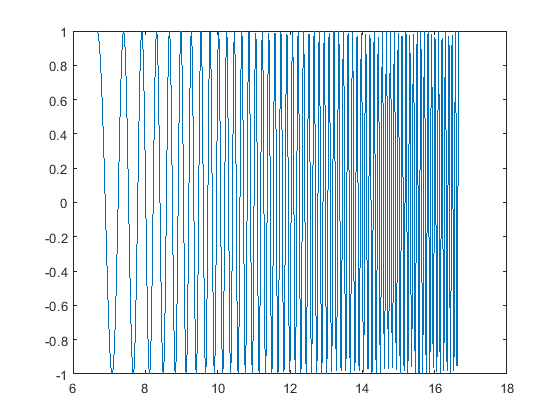


% default와 높이 차이가 있는 signal
tt = diff_t : dt : 10+diff_t;   % [ns]
rt = chirp_gain.*cos(2*pi.*(chirp_fo*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
plot(tt,rt);

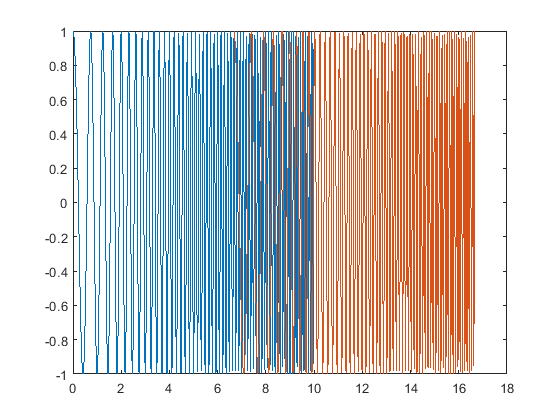


plot(t,xt);
hold on;
plot(tt,rt);
hold off;

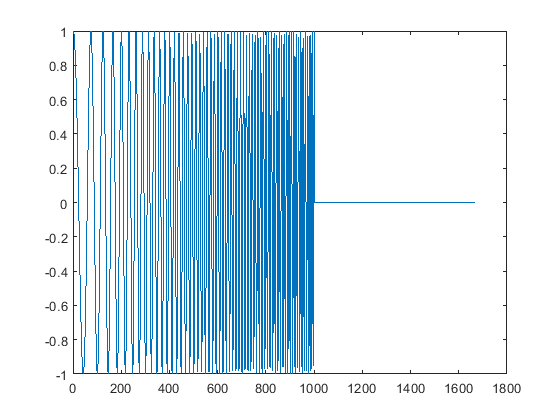


% 지표에 부딪쳐 들어오는 signal들의 합
rtt1 = [xt, zeros(1,round(diff_t*10^2))];
plot(rtt1)

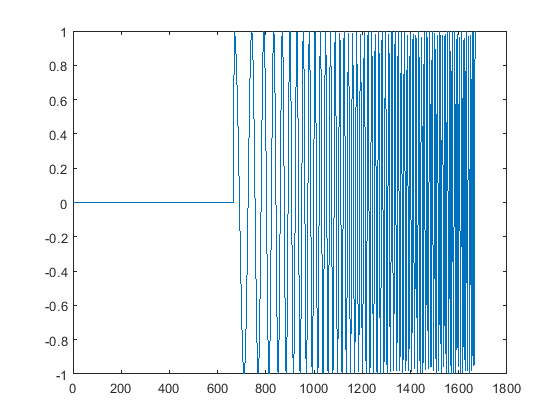

rtt2 = [zeros(1,round(diff_t*10^2)), xt];
plot(rtt2)

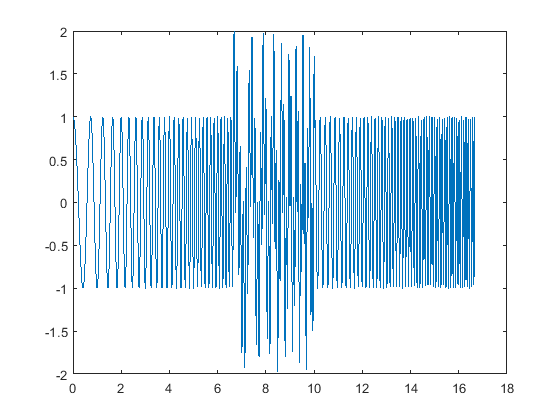

rtt = rtt1 + rtt2;
plot((0:length(rtt)-1)*dt,rtt);

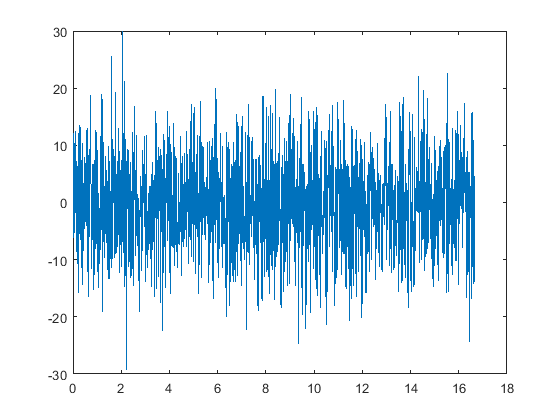


rtt_with_noise = (rtt1 + rtt2) + noiseSD*randn(1,length(rtt));
plot((0:length(rtt)-1)*dt,rtt_with_noise);

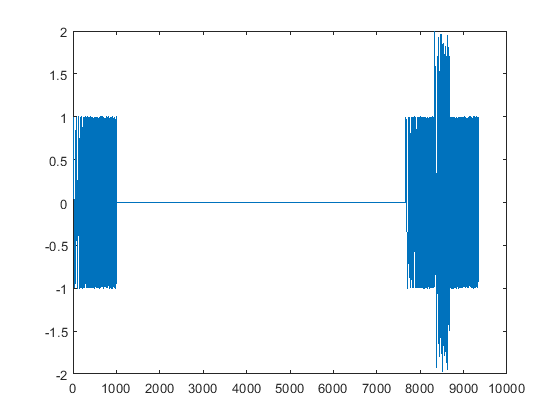


total_signal = [st, rtt];       % 같은 높이의 input data는 동시에 들어온다고 가정. received signal은 두 개.
plot(total_signal);

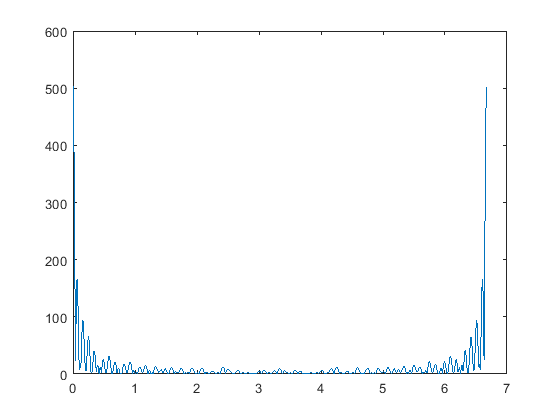


% correlation processor
ct = length(rtt)-length(t);
for i = 0:ct
    corr(i+1) = rtt(i+1:i+length(t)) * xt';
    corr_with_noise(i+1) = rtt_with_noise(i+1:i+length(t)) * xt';
end

plot((0:length(corr)-1)*dt,abs(corr));                              % standard devitaion이 6이상이면 오차발생!

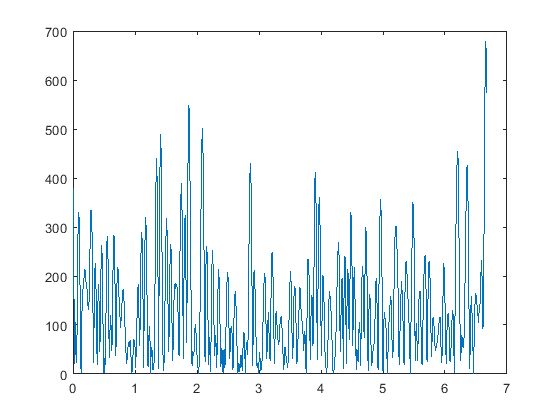

plot((0:length(corr_with_noise)-1)*dt,abs(corr_with_noise));        % noise가 있을 때의 correlation



% 따라서 빔폭 size에 따른 signal data의 correlation 결과와 점을 찍는 것 연결!!
% correlation 결과에서 max값 비교! ex) x축이 0, 6.67일 때 max값을 가지면 완벽히 1m 분해능을 가지게 된다.
% x축(시간 [ns])을 거리로 환산하고 R 에서 뺀 다음 round 하면 output data가 나온다.
% chirp을 이용한 pulse compression 방법 이용하여 noise에 대한 타격이 적어 더 분해능이 좋아짐?
% only noise vs noise with pulse compression 비교하여 분해능 분석!!

cp_length1 = (length(rtt)-length(t)+1)/2

cp_length1 = 334

cp_length2 = length(rtt)-length(t)+1

cp_length2 = 668

cp_resolution1 = corr_with_noise(1:cp_length1);
cp_resolution2 = corr_with_noise(cp_length1:cp_length2);

[m1,k1] = max(cp_resolution1)             % m : 최댓값, k1 : sample number

m1 = 549.2702

k1 = 188

[m2,k2] = max(cp_resolution2)

m2 = 679.1299

k2 = 334

% [n,k] = maxk(cp_resolution1,2)          % 가장 큰녀석 두개의 max값과 sample number

arived_time1 = (k1-1)*10^-2               % correlation의 결과로 얻은 signal의 시간

arived_time1 = 1.8700

arived_time2 = (k2-1)*2*10^-2   

arived_time2 = 6.6600

arived_time = [arived_time1, arived_time2];

arived_rt1_R = (((arived_t1 +(arived_time(1)*10^-3))*c/2)*10^-6) - R    % 첫번째 신호로부터 얻은 거리

arived_rt1_R = 0.2805

arived_rt2_R = (((arived_t1 +(arived_time(2)*10^-3))*c/2)*10^-6) - R    % 두번쨰 신호로부터 얻은 거리

arived_rt2_R = 0.9990

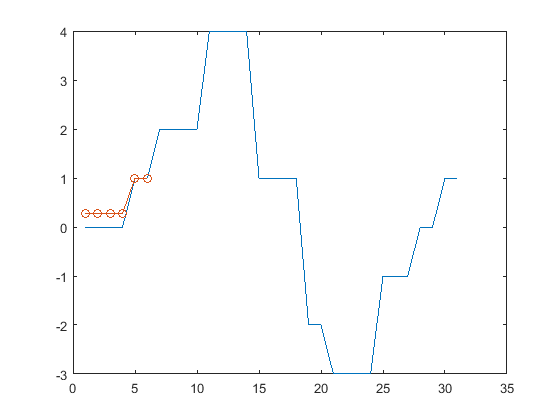


% correlation을 거친 최종 output data
if arived_rt1_R < arived_rt2_R
    output_matrix = [arived_rt1_R, arived_rt1_R, arived_rt1_R, arived_rt1_R, arived_rt2_R, arived_rt2_R];
elseif arived_rt1_R > arived_rt2_R
    output_matrix = [arived_rt2_R, arived_rt2_R, arived_rt2_R, arived_rt2_R, arived_rt1_R, arived_rt1_R];
end

plot(ground);
hold on;
plot(output_matrix,'Marker','o');
hold off;


% processing 과정이 없는 것과 비교
plot(ground);
hold on;
plot(first_input_with_noise,'Marker','o');
hold off;

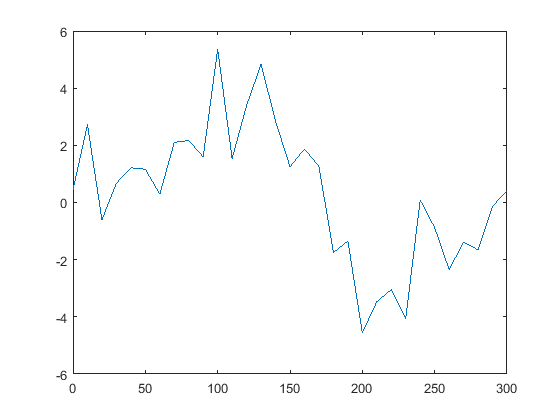


plot(x,final_ground);